% -------------------------------------------------------------------------
% 4DB00 Dynamics and control of mechanical systems 2020-2021
% CNC challenge.
% -------------------------------------------------------------------------
clc;close all;clearvars
addpath Toolbox
open_system('Toolbox/CNC_Simulink', 'loadonly')

## Symbols

Define the degrees of freedom and their first two derivative w.r.t. time as symbolic expressions

syms xc dxc ddxc yb dyb ddyb phih dphih ddphih

% Define the system parameters, actuator force and time
% as symbolic expressions
syms g Lf Lb L23 L24 wc hc mf mb mc mh Jh2 kPD dPD dx kphi dphi xref phiref phih3
syms Mphi
syms t
syms func

% Place degrees of freedom (and their derivatives) in the generalized
% coordinates and the prescribed displacements.
Components.q        = [xc;phih];
Components.dq       = [dxc;dphih];
Components.ddq      = [ddxc;ddphih];
Components.s_pd     = [yb];
Components.ds_pd    = [dyb];
Components.dds_pd   = [ddyb];
Components.F        = [Mphi];
Components.time     = [t];

% Define system parameters as symbols
Components.parameters.g.symbol  = g;
Components.parameters.Lf.symbol = Lf;
Components.parameters.Lb.symbol = Lb;
Components.parameters.L23.symbol = L23;
Components.parameters.L24.symbol = L24;
Components.parameters.wc.symbol = wc;
Components.parameters.hc.symbol = hc;
Components.parameters.mf.symbol = mf;
Components.parameters.mb.symbol = mb;
Components.parameters.mc.symbol = mc;
Components.parameters.mh.symbol = mh;
Components.parameters.Jh2.symbol = Jh2;
Components.parameters.kPD.symbol = kPD;
Components.parameters.dPD.symbol = dPD;
Components.parameters.dx.symbol = dx;
Components.parameters.kphi.symbol = kphi;
Components.parameters.dphi.symbol = dphi;
Components.parameters.xref.symbol = xref;
Components.parameters.phiref.symbol = phiref;
Components.parameters.phih3.symbol = phih3;

## ------------------------------------------------------------------------

%--------------------------------------------------------------------------
%--------> Please complete the following code for Deliverable 1:
%--------------------------------------------------------------------------
%--------------------------------------------------------------------------

% Insert the system parameter values:
Components.parameters.g.value      = [9.81]; %m/(s^2)   (gravity acceleration)
Components.parameters.Lf.value     = [1]; %m            (Length of the vertical frames)
Components.parameters.Lb.value     = [0.8]; %m          (Length of the horizontal beam)
Components.parameters.L23.value    = [0.05]; %m         (Distance between points 2 and 3)
Components.parameters.L24.value    = [0.1]; %m          (Distance between points 2 and 4)
Components.parameters.wc.value     = [0.1]; %m          (Width of the carraige)
Components.parameters.hc.value     = [0.08]; %m         (Height of the carriage)
Components.parameters.mf.value     = [10]; %kg          (Mass of the frame)
Components.parameters.mb.value     = [10]; %kg          (Mass of the beam)
Components.parameters.mc.value     = [1.5]; %kg         (Mass of the carriage)
Components.parameters.mh.value     = [0.5]; %kg         (Mass of the milling head)
Components.parameters.Jh2.value    = [0.5]; %kg*m^2     (Rotational ineratia of the milling head)
Components.parameters.kPD.value    = [350]; %N/m        (PD controller P gain)
Components.parameters.dPD.value    = [10]; %N*s/(m)     (PD controller D gain)
Components.parameters.dx.value     = [0.5]; %N*s/(m)    (Damping coefficient of the carraige)
Components.parameters.kphi.value   = [500]; %N*m/rad    (Spring coefficient of the band brake)
Components.parameters.dphi.value   = [2]; %N*m*s/rad    (Damping coefficient of the band brake)
Components.parameters.xref.value   = [0.5]; %m          (Reference position of carraige)
Components.parameters.phiref.value = [-pi/2]; %rad      (Reference angle of band brake)
Components.parameters.phih3.value  = [-2*pi/3]; %rad    (Relative angles of mass mh)


% Insert symbolic expressions for the kinetic and potential energy
% and the generalized forces:
T   = [0.5*dyb^2*(mb+mc+mh)+0.5*dxc^2*(mc+mh)+0.5*dphih^2*(Jh2+mh*L23^2)-mh*dphih*L23*(dxc*sin(phih3+phih)+dyb*cos(phih3+phih))]   % Kinetic energy %

$$T = \frac{{\mathrm{dphih}}^{2}\,\left(\mathrm{mh}\,{L_{23}}^{2}+{\mathrm{Jh}}_{2}\right)}{2}+\frac{{\mathrm{dxc}}^{2}\,\left(\mathrm{mc}+\mathrm{mh}\right)}{2}+\frac{{\mathrm{dyb}}^{2}\,\left(\mathrm{mb}+\mathrm{mc}+\mathrm{mh}\right)}{2}-L_{23}\,\mathrm{dphih}\,\mathrm{mh}\,\left(\mathrm{dyb}\,\cos\left(\mathrm{phih}+{\mathrm{phih}}_{3}\right)+\mathrm{dxc}\,\sin\left(\mathrm{phih}+{\mathrm{phih}}_{3}\right)\right)$$

V   = [g*((mb+mc+mh)*(yb)-L23*mh*sin(phih3+phih))+ 0.5*kphi*(phih-phiref)^2+0.5*kPD*(xc-xref)^2]   % Potential energy

$$V = g\,\left(\mathrm{yb}\,\left(\mathrm{mb}+\mathrm{mc}+\mathrm{mh}\right)-L_{23}\,\mathrm{mh}\,\sin\left(\mathrm{phih}+{\mathrm{phih}}_{3}\right)\right)+\frac{\mathrm{kphi}\,{\left(\mathrm{phih}-\mathrm{phiref}\right)}^{2}}{2}+\frac{\mathrm{kPD}\,{\left(\mathrm{xc}-\mathrm{xref}\right)}^{2}}{2}$$

Qnc = [-(dPD+dx)*dxc;-dphi*dphih]   % Generalised forces

$$Qnc = \left(\begin{array}{c} -\mathrm{dxc}\,\left(\mathrm{dPD}+\mathrm{dx}\right)\\ -\mathrm{dphi}\,\mathrm{dphih} \end{array}\right)$$


% Calculate the non-linear equations of motion (statement is complete):
Nonlinear_EOM = DOMS('NonlinearEOM',Components,T,V,Qnc);

% Insert the settings for the simulation:
t_sim     = [5];  % Simulation time
q_init    = [0.1;-pi/4];  % Initial value for q
dq_init   = [0;0];  % Initial value for dq
s_pd_of_t = [0.5 + 0.1*sin(10*t)];  % Prescribed displacement a function of time t (e.g. sin(t))
M_of_t    = [100*sin(3*t)];  % External force as a function of time t (e.g. cos(t))

% Simulate the non-linear equations of motion (statement is complete):
Sim_Nonlinear = DOMS('Sim_Nonlinear',Components, Nonlinear_EOM,...
    t_sim,q_init,dq_init,s_pd_of_t,M_of_t);

% Simulate the virtual test setup in Simulink (statement is complete):
Sim_Setup  = DOMS('Sim_Setup',Components,t_sim,...
    q_init,dq_init,s_pd_of_t, M_of_t);


%--------------------------------------------------------------------------

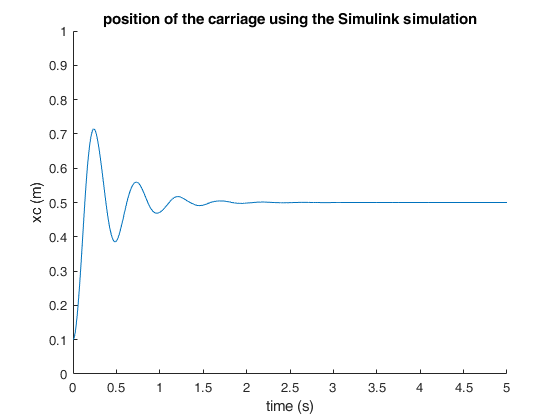


figure(1)
clf;    %clearing the figure
hold on;

plot(Sim_Setup.t,Sim_Setup.qt(:,1)) %plotting data
%plot(Sim_Nonlinear.t,Sim_Nonlinear.qt(:,1))

%legend("Simulink simulation","Non Linear equation of motion simulation") % setting legend
title("position of the carriage using the Simulink simulation") %"position of the carriage using the Non Linear equation of motion simulation"  ,   "position of the carriage using the Simulink simulation"
ylabel("xc (m)") 
xlabel("time (s)")
xlim([0 5])
ylim([0 1])

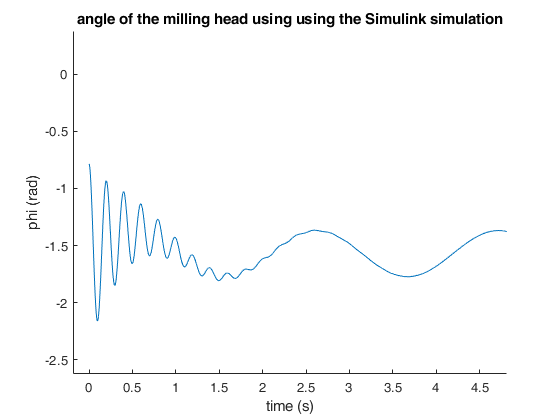


figure(2)
clf
hold on
plot(Sim_Setup.t,Sim_Setup.qt(:,2))
%plot(Sim_Nonlinear.t,Sim_Nonlinear.qt(:,2))
%legend("position of the carriage using the Simulink simulation") %
title( "angle of the milling head using using the Simulink simulation") % "angle of the milling head using the Non Linear equation of motion simulation"    ,   "angle of the milling head using using the Simulink simulation"
ylabel("phi (rad)")
xlabel("time (s)")
xlim([0 5])
ylim([-3 0])


%--------------------------------------------------------------------------



% This statement stops the script here.
% Remove or comment it, if you wish to continue with deliverable 2

## ------------------------------------------------------------------------

%--------------------------------------------------------------------------
%--------> Please complete the following code for Deliverable 2:
%--------------------------------------------------------------------------
%--------------------------------------------------------------------------






%Insert the linearization points
q_0_stable = [0.5; -1.570];   %Stable equilibrium for linearization
q_0_given  = [0.2; 0];   %Given equilibrium for linearization

% Linearize the equations of motion (statements are complete):
LinearEOM_stable   = DOMS('Linearize',Components,Nonlinear_EOM,q_0_stable);
LinearEOM_given    = DOMS('Linearize',Components,Nonlinear_EOM,q_0_given);

% Insert the settings for the simulation:
t_sim             = [3];   % Simulation time
q1_init           = [0.35;-pi/4];     %initial value for q
q1_init_stable    = q1_init - q_0_stable;   % Initial value for q1
q1_init_given     = q1_init - q_0_given;   % Initial value for q1
dq1_init_stable   = [0; 0];   % Initial value for dq1
dq1_init_given    = [0; 0];   % Initial value for dq1
M_of_t           = [0];    % External force as a function of time t (e.g. cos(t))
s_pd_of_t = [0];


% Simulate the linear equations of motion (statements are complete):
Sim_Linear_stable   = DOMS('Sim_Linear',Components,LinearEOM_stable,...
    t_sim,q1_init_stable,dq1_init_stable, M_of_t);
Sim_Linear_given    = DOMS('Sim_Linear',Components,LinearEOM_given,...
    t_sim,q1_init_given,dq1_init_given, M_of_t);

Sim_Setup_stable = DOMS('Sim_Setup',Components,t_sim,...
    q1_init,dq1_init_stable,s_pd_of_t, M_of_t);




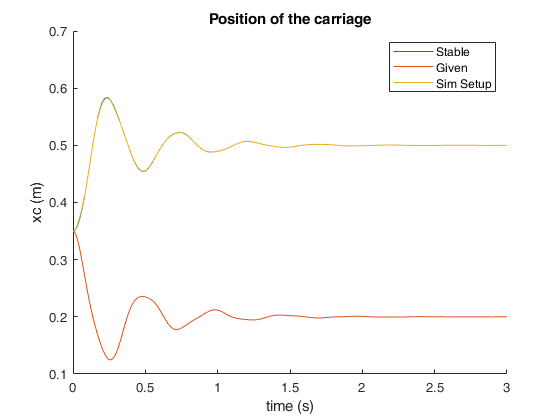


%--------------------------------------------------------------------------
figure(1)
clf;    %clearing the figure
hold on;

plot(Sim_Linear_stable.t,Sim_Linear_stable.q1t(:,1)+q_0_stable(1)) %plotting data
plot(Sim_Linear_given.t,Sim_Linear_given.q1t(:,1)+q_0_given(1))
plot(Sim_Setup_stable.t,Sim_Setup_stable.qt(:,1))

legend("Stable","Given","Sim Setup") % setting legend
title("Position of the carriage") %"xc of the Non Linear equation of motion simulation"  ,   "xc of the Simulink simulation"
ylabel("xc (m)") 
xlabel("time (s)")
xlim([0;3])
ylim([0.1;0.7])

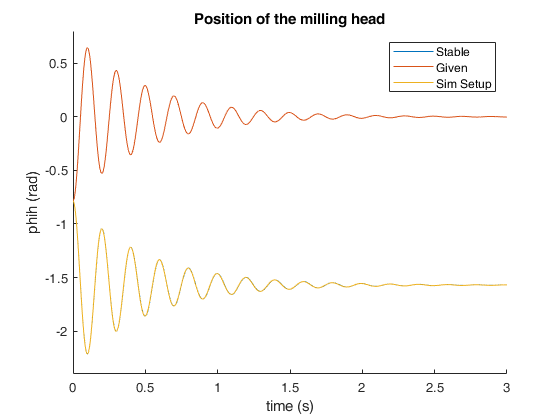

figure(2)
clf;    %clearing the figure
hold on;

plot(Sim_Linear_stable.t,Sim_Linear_stable.q1t(:,2)+q_0_stable(2)) %plotting data
plot(Sim_Linear_given.t,Sim_Linear_given.q1t(:,2)+q_0_given(2))
plot(Sim_Setup_stable.t,Sim_Setup_stable.qt(:,2))

legend("Stable","Given","Sim Setup") % setting legend
title("Position of the milling head") %"xc of the Non Linear equation of motion simulation"  ,   "xc of the Simulink simulation"
ylabel("phih (rad)") 
xlabel("time (s)")
xlim([0;3])
ylim([-2.4;0.8])

%--------------------------------------------------------------------------
